## **CYKLY SPALOVACÍCH MOTORŮ - OTTŮV CYKLUS**

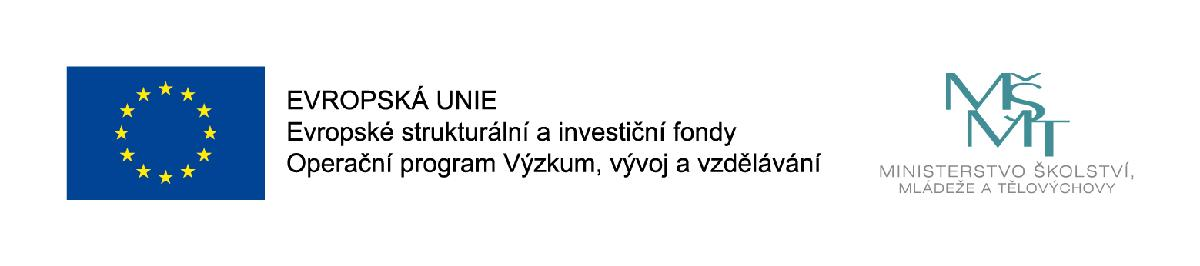

#### prof. Ing. Josef ŠTĚTINA, Ph.D. / Vysoké učení technické v Brně

#### email: [josef.stetina@vutbr.cz](mailto:josef.stetina@vutbr.cz)

#### www: [http://termomechanika.online/](http://termomechanika.online/)

#### www: [http://bit.ly/termomechanika_online/](http://bit.ly/termomechanika_online/)

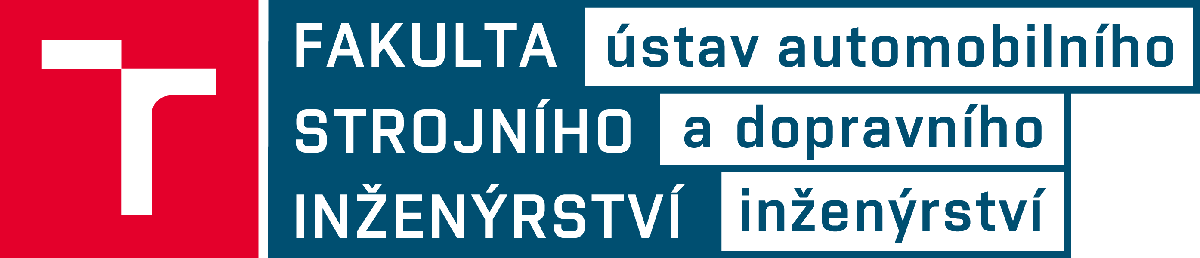

**Zjednodušení zavedená u teoretických cyklů s ideálními plyny**

- Množství a složení plynu v soustavě se nemění (uzavřená soustava)

- Cyklus probíhá s ideálními plyny, fyzikální vlastnosti (*c**p**, **c**v**, κ* aj. ) jsou nezávislé na teplotě

- Hoření nahrazujeme přívodem tepla z okolí

- Výfuk nahrazujeme odvodem tepla do okolí

- Jednotlivé děje nahrazujeme vratnými termodynamickými ději, komprese a expanze bývají adiabatické (nebo technické polytropy

Zážehové motory nebo-li motory na lehce vypařitelná paliva (benzínové, LPG, CNG) se sv94kou.

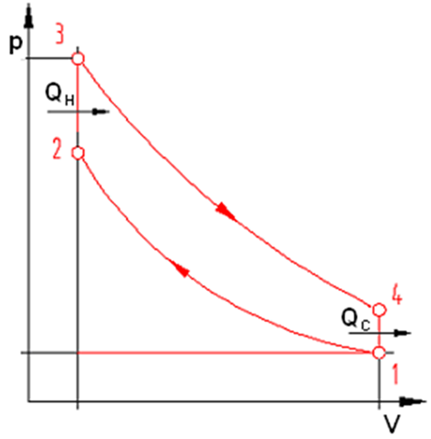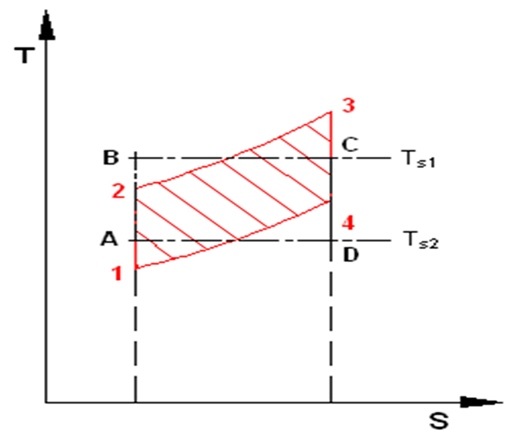

4-dobý motor  0-1-2-3-4-1-0

2-dobý motor  1-2-3-4-1

Zdvihový objem              $V_Z=V_1-V_2$  

Kompresní objem          $V_K=V_2$

Kompresní poměr          $${\epsilon} = \frac{V_1}{V_2}$$

Cyklus zážehového motoru, nazývaný *Ottův, *se skládá ze dvou izochor a ze dvou adiabat. Podle tohoto cyklu pracují zážehové motory na plynná nebo lehce odpařitelná paliva. Postup změn u čtyřtaktního motoru je tento: Během prvního zdvihu se nasává do válce teoreticky při atmosférickém tlaku (ve skutečnosti s malým podtlakem) směs plynu nebo benzinových par se vzduchem. Po uzavření sacího-ventilu nastává druhý zdvih, při němž se nasátá směs komprimuje na takový tlak, aby konečná kompresní teplota byla nižší než teplota vznícení směsi. Na konci tohoto kompresního zdvihu se směs zažehne elektrickou jiskrou. Zažehuje se prakticky s určitým předstihem, aby se dosáhlo co možno izochorického průběhu spalování, a tím vyššího maximálního spalovacího tlaku. Jinak by při zpětném pohybu pístu (třetím zdvihu) následkem vzrůstajícího objemu tlak při spalování stoupal se sklonem vpravo a maximální tlak by byl nižší. Třetí zdvih (takt) je expanzní. Před ukončením expanzního zdvihu se otevře výfukový ventil a plyny se při čtvrtém zdvihu vytlačí z válce za mírného stálého přetlaku.

Přívedené a odvedené teplo:


$$${Q_H} = m{c_V}({T_3} - {T_2})$$$
                            
$$${Q_C} = m{c_V}({T_1} - {T_4})$$$


Výpočet termické účinnosti:


$$${\eta _t} = 1 - \frac{{m{c_V}({T_4} - {T_1})}}{{m{c_V}({T_3} - {T_2})}} = 1 - \frac{{{T_4} - {T_1}}}{{{T_3} - {T_2}}}$$$


Ve vzorci pro termickou účinnost

- pokrátíme zlomek teplotou *T**2*

- 1. člen čitatele vynásobíme *T**3**/**T**3*


$$$\frac{{{T_1}}}{{{T_2}}} = {\left( {\frac{{{v_2}}}{{{v_1}}}} \right)^{\kappa  - 1}} = {\left( {\frac{{{v_3}}}{{{v_4}}}} \right)^{\kappa  - 1}} = \frac{{{T_4}}}{{{T_3}}}$$$



$$${\eta _t} = 1 - \frac{{\frac{{{T_1}}}{{{T_2}}}\left( {\frac{{{T_3}}}{{{T_2}}} - 1} \right)}}{{\frac{{{T_3}}}{{{T_2}}} - 1}} = 1 - \frac{{{T_1}}}{{{T_2}}} = 1 - {\left( {\frac{{{v_2}}}{{{v_1}}}} \right)^{\kappa  - 1}}$$$


Konečný vytah pro termickou účinnot:

# 
$$${\eta _t} = 1 - {\left( {\frac{1}{\varepsilon }} \right)^{\kappa  - 1}}$$$


# 
$$${\eta _t} = f\left( {\kappa ,\;\varepsilon } \right)$$$


Účinnost zážehového cyklu roste se stoupajícím kompresním poměrem. Podle tohoto výrazu závisí termická účinnost též na poissonově konstantě*. *Účinnost zážehového cyklu roste tedy s rostoucí hodnotou poissonově konstantě*, *tj. s menším počtem atomů v molekule plynu.

Jak bylo již dříve uvedeno, je zvyšování termické účinnosti zážehového cyklu zvětšováním kompresního poměru je omezeno teplotou vznícení nasáté směsi. Pří­pustný stupeň komprese e se tudíž pro různá paliva značně liší.

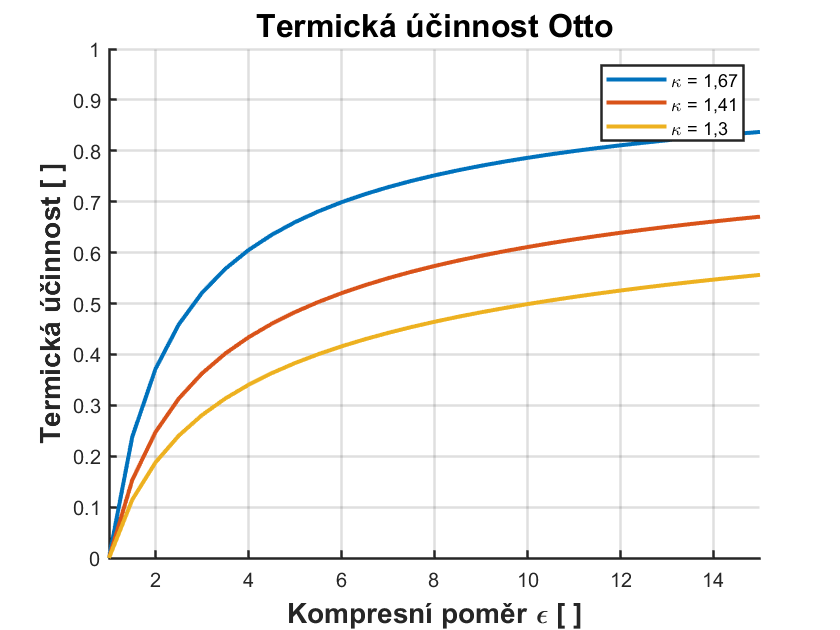

subplot(1,1,1);
i = 1;
eps_v = zeros(1, 29);
eta_t_1 = zeros(1, 29);
eta_t_2 = zeros(1, 29);
eta_t_3 = zeros(1, 29);
for eps=1:0.5:15
    eps_v(i) = eps;
    eta_t_1(i) = 1-(1/eps)^(kappaB(1)-1);
    eta_t_2(i) = 1-(1/eps)^(kappaB(2)-1);
    eta_t_3(i) = 1-(1/eps)^(kappaB(3)-1);
    i = i + 1;
end
title('Termická účinnost Otto','FontSize', 16 , 'FontName', 'Helvetica','FontWeight','bold');
xlabel('Kompresní poměr \epsilon [ ]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
ylabel('Termická účinnost [ ]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
xlim([1 15]);
ylim([0 1]);
set(gca, 'linewidth',1.2);
hold on;
plot(eps_v,eta_t_1,'-','linewidth',2);
plot(eps_v,eta_t_2,'-','linewidth',2);
plot(eps_v,eta_t_3,'-','linewidth',2);
grid on;
legend('\kappa = 1,67','\kappa = 1,41','\kappa = 1,3')
hold off;

# $${\eta _t}$$lze zvyšovat kompresním poměrem

### Příklad

Pracovní látkou zážehového čtyřdobého motoru je ideálním plyn s plynovou konstantou 289,7 J/kgK, který uvažujeme jako tříatomový. Měrná tepla uvažujte konstantní. Objem válce 0,25 litrů, tlak nasávaného vzduchu je 1000 hPa a teplota 24 °C a kompresní poměr 10,5. Maximální teplota cyklu je 2700 °C. 

Určete stavové veličiny v charakteristických bodech cyklu, přivedené teplo, odvedené teplo, práci cyklu a termickou účinnost, střední teoretický tlak, Stanovete maximální výkon při otáčkách maximálního výkonu jsou 5000 1/min, pokud je motor čyřválcový. Nakreslete p-v a T-s diagram.

V1l   = 0.25;      % [l] objem válce
p1hPa = 1000;      % [hPa] tlak nasávaného vzduchu
t1C   = 24;        % [°C]  teplota nasávaného vzduchu
eps   = 10.5;      % [-]  kompresní poměr
t3C   = 2700;      % [°C]  maximální teplota cyklu
notacky = 5000.0;  % [1/min] otáčky motoru
r = 289.7;         % [J/kgK] plynová konstanta
kappa = 1.3;       % předpokládáme spíše tříatomové plyny, benzínové výpary a spaliny

Výpočet vlastností plynu

cv = 1/(kappa-1) * r;
cp = cv * kappa;

Bod 1

T1 = C2K(t1C);
p1 = hPa2Pa(p1hPa);
V1 = l2m3(V1l);
m1 = p1*V1/(r*T1)

m1 = 2.9041e-04

Bod 2

V2 = V1/eps;
p2 = p1 * eps^kappa;
T2 = p2*V2/(r*m1);

Bod 3

V3 = V2;
T3 = C2K(t3C);
p3 = p2*T3/T2;

Bod 4

p4 = p3 *(V3/V1)^kappa;
V4 = V1;
T4 = T1*(p4/p1);

## Data pro kreslení grafů

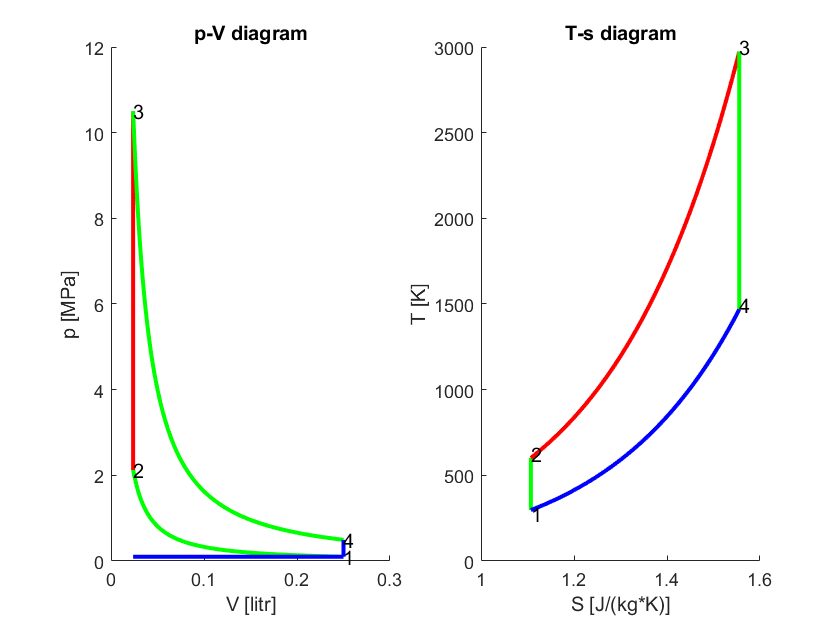

Vv1 = linspace(V1,V2,180);
pv1 = zeros([1,180]);
Tv1 = zeros([1,180]);
Sv1 = zeros([1,180]);
for i=2:180
  pv1(i) = p1*V1^kappa/Vv1(i)^kappa;
  Tv1(i) = pv1(i) * Vv1(i) / (r * m1);
  Sv1(i)=m1*cp*log(Tv1(i))-m1*r*log(pv1(i));
end
pv1(1) = p1;
pv1(180) = p2;
Vv1(1) = V1;
Vv1(180) = V2;
Tv1(1) = pv1(1) * Vv1(1) / (r * m1);
Sv1(1)=m1*cp*log(Tv1(1))-m1*r*log(pv1(1));

pv2 = linspace(p2,p3,180);
Vv2 = zeros([1,180]);
Tv2 = zeros([1,180]);
Sv2 = zeros([1,180]);
for i=2:180
  Vv2(i)= V2;
  Tv2(i) = pv2(i) * Vv2(i) / (r * m1);
  Sv2(i)=m1*cp*log(Tv2(i))-m1*r*log(pv2(i));
end
pv2(1) = p2;
pv2(180) = p3;
Vv2(1) = V2;
Vv2(180) = V3;
Tv2(1) = pv2(1) * Vv2(1) / (r * m1);
Sv2(1)=m1*cp*log(Tv2(1))-m1*r*log(pv2(1));

Vv3 = linspace(V3,V4,180);
pv3 = zeros([1,180]);
for i=2:180
  pv3(i)=p3*V3^kappa/Vv3(i)^kappa;
  Tv3(i) = pv3(i) * Vv3(i) / (r * m1);
  Sv3(i)=m1*cp*log(Tv3(i))-m1*r*log(pv3(i));    
end
pv3(1) = p3;
pv3(180) = p4;
Vv3(1) = V3;
Vv3(180) = V4;
Tv3(1) = pv3(1) * Vv3(1) / (r * m1);
Sv3(1)=m1*cp*log(Tv3(1))-m1*r*log(pv3(1));    

pv4 = linspace(p4,p1,180);
Vv4 = zeros([1,180]);
Tv4 = zeros([1,180]);
Sv4 = zeros([1,180]);
for i=2:180
  Vv4(i)= V4;
  Tv4(i) = pv4(i) * Vv4(i) / (r * m1);
  Sv4(i)=m1*cp*log(Tv4(i))-m1*r*log(pv4(i));
end
pv4(1) = p4;
pv4(180) = p1;
Vv4(1) = V4;
Vv4(180) = V1;
Tv4(1) = pv4(1) * Vv4(1) / (r * m1);
Sv4(1)=m1*cp*log(Tv4(1))-m1*r*log(pv4(1));

Vv0 = linspace(V1,V2,180);
pv0 = zeros([1,180]);
for i=2:180
  pv0(i)= p1;
end
pv0(1) = p1;
pv0(180) = p1;
Vv0(1) = V1;
Vv0(180) = V2;

% Vykreslení diagramu
figure;
subplot(1,2,1);
hold on;
plot(Vv1*10^3,pv1/10^6,'g-','linewidth',2);
plot(Vv2*10^3,pv2/10^6,'r-','linewidth',2);
plot(Vv3*10^3,pv3/10^6,'g-','linewidth',2);
plot(Vv4*10^3,pv4/10^6,'b-','linewidth',2);
plot(Vv0*10^3,pv0/10^6,'b-','linewidth',2);
hold off;
% popis bodů diagramu
text(Vv1(1)*10^3,(pv1(1)-0.2)/10^6,'1');
text(Vv2(1)*10^3,(pv2(1)-0.2)/10^6,'2');
text(Vv3(1)*10^3,(pv3(1)+0.2)/10^6,'3');
text(Vv4(1)*10^3,(pv4(1)+0.2)/10^6,'4');
% název grafu a popisy os
title('p-V diagram')
xlabel('V [litr]')
ylabel('p [MPa]')                     
subplot(1,2,2);
hold on;
plot(Sv1,Tv1,'g-','linewidth',2);
plot(Sv2,Tv2,'r-','linewidth',2);
plot(Sv3,Tv3,'g-','linewidth',2);
plot(Sv4,Tv4,'b-','linewidth',2);
hold off;
% popis bodů diagramu
text(Sv1(1),Tv1(1)-25,'1');
text(Sv2(1),Tv2(1)+25,'2');
text(Sv3(1),Tv3(1)+25,'3');
text(Sv4(1),Tv4(1)+25,'4');
% název grafu a popisy os
title('T-s diagram')
xlabel('S [J/(kg*K)]')
ylabel('T [K]')                      % ^\circC

###  Tepla a práce


QH = m1 * cv * (T3-T2);
QC = m1 * cv * (T1-T4);
A0 = QH - abs(QC);
Qh = m1 * cv*(T3-T2);
Qc = m1 * cv *(T1-T4);
Ao = Qh - abs(Qc);
% Výkon čtyřdobého motoru
Pt = Ao * notacky/60.0/2.0;
% Termická účinnost
etat = Ao / Qh;
% výstupní data
clc;
fprintf('p1 : %.1f kPa V1 : %.1f ccm T1 :  %.1f K \n',Pa2kPa(p1), V1*1000000.0, T1);

p1 : 100.0 kPa V1 : 250.0 ccm T1 :  297.1 K 


fprintf('p2 : %.1f kPa V2 : %.1f ccm T2 :  %.1f K \n',Pa2kPa(p2), V2*1000000.0, T2);

p2 : 2125.9 kPa V2 : 23.8 ccm T2 :  601.6 K 


fprintf('p3 : %.1f kPa V3 : %.1f ccm T3 :  %.1f K \n',Pa2kPa(p3), V3*1000000.0, T3);

p3 : 10505.8 kPa V3 : 23.8 ccm T3 :  2973.2 K 


fprintf('p4 : %.1f kPa V4 : %.1f ccm T4 :  %.1f K \n',Pa2kPa(p4), V4*1000000.0, T4);

p4 : 494.2 kPa V4 : 250.0 ccm T4 :  1468.5 K 


fprintf('Přivedené teplo  : %.1f [J]\n',Qh);

Přivedené teplo  : 665.1 [J]


fprintf('Odvedené teplo   : %.1f [J]\n',Qc);

Odvedené teplo   : -328.5 [J]


fprintf('Práce cyklu      : %.1f [J]\n',Ao);

Práce cyklu      : 336.6 [J]


fprintf('Výkon motoru     : %.1f [kW]\n',W2kW(Pt));

Výkon motoru     : 14.0 [kW]


fprintf('Termická účinnost: %.3f\n',etat);

Termická účinnost: 0.506


### Rozměry motoru, střední teoretický indikovaný tlak

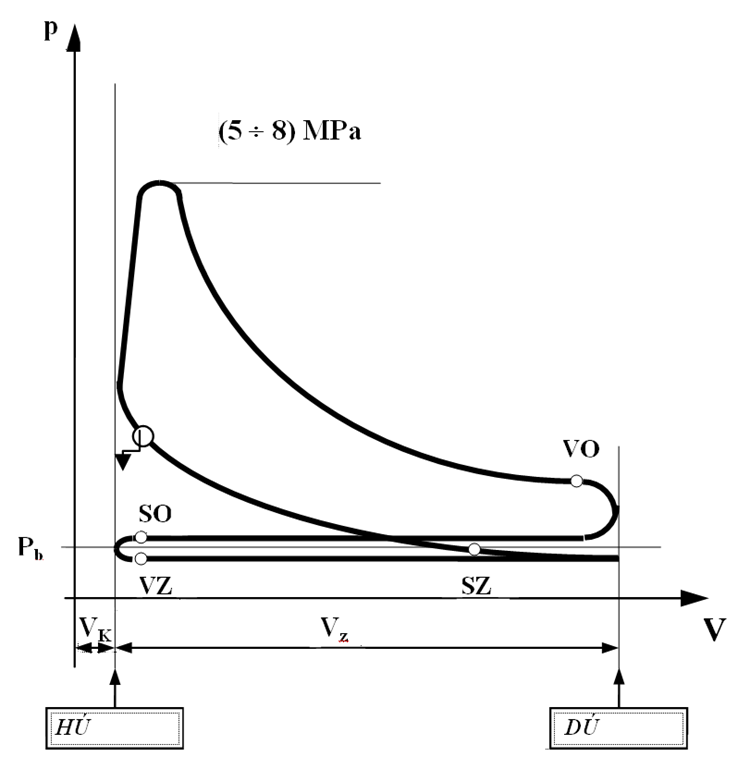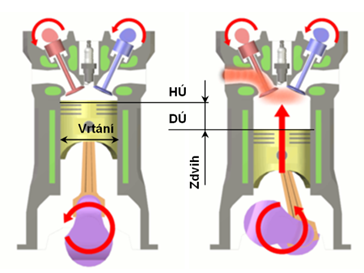

**HÚ** – horní úvrať, horní mrtvá poloha (TDC)

**DÚ** – dolní úvrať, dolní mrtvá poloha (BDC)

**Vrtání** – průměr válce    D [mm]

**Zdvih **– dráha mezi HÚ – DÚ   Z [mm]

**Kompresní objem **– objem nad pístem v HÚ

**Zdvihový objem **– objem mezi HÚ do DÚ

**Objem válce** – Kompresní + zdvihový

**Kompresní poměr**


$$${\epsilon  = \frac{ObjemobsazenyplynemvDU}{ObjemobsazenyplynemHU} > 1}$$$


Uspalovacích motorů je mezi horní úvratí  polohy dna pístu, a víkem válce prostor o objemu Vk (na obrázku je *V**k**= V**2**), *který se nazývá u spalovacích motorů *spalovací prostor.*  Objem, který odpovídá zdvihu pístu *(Z= 2R) *z jedné krajní polohy do druhé, nazýváme *zdvihový objem **V**z* objemy *V**k** + **V**z* tvoří *celkový objem válce V.*

Poměr celkového objemu válce k objemu spalovacího prostoru nazýváme *stupeň komprese.*

*Výpočet zdvihového objemu:*


$$${V_z=\frac{\pi.D^2}{4}Z}$$



$$${V_k=\frac{V_z}{\epsilon-1}}$$


#### **STŘEDNÍ TEORETICKÝ TLAK PRACOVNÍCH OBĚHŮ**

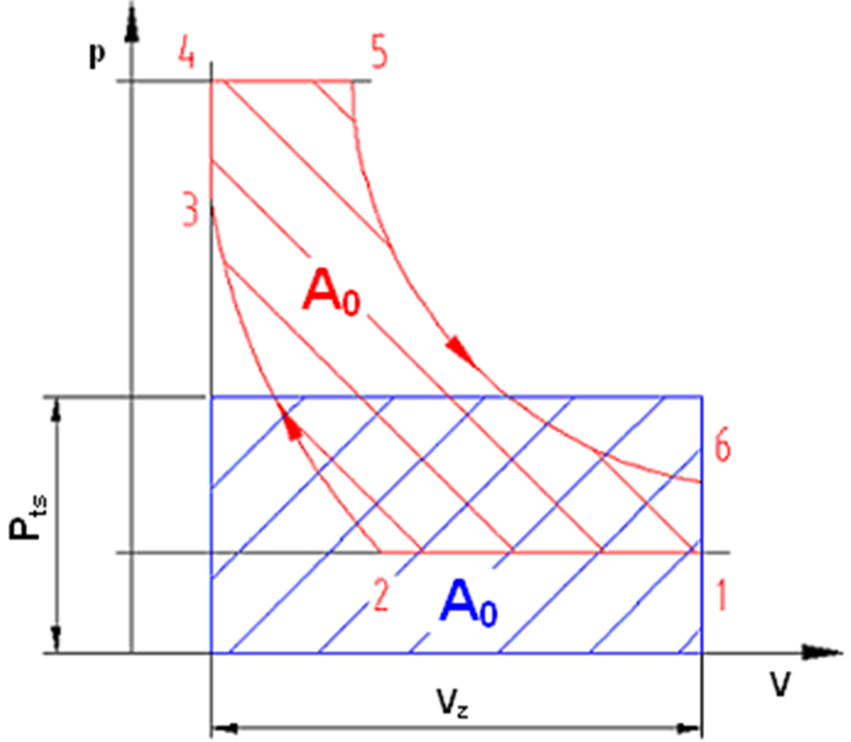

Je pomyslný konstantní tlak působící na píst, který by na dráze jednoho zdvihu vykonal na klikové hřídeli motoru stejnou práci, jako skutečný proměnlivý tlak na dráze čtyř zdvihů (čtyřdobý motor).

$${p_{ts}=\frac{A_o}{V_z}}$            [MPa]

Výužití středního teoretického tlaku pro výpočet teoretického výkonu a točivého momentu. Typické hodnoty středního teoretického tlaku se pohybují mezi 1,2 až 2,0 MPa.

$${P_t} = \frac{{{A_0}\cdot{n_o}\cdot i_{valcu}}}{2} = \frac{{{{{p}}_{{{ts}}}} \cdot {{{V}}_{{z}}} \cdot {{n_o}\cdot i_{valcu}}}}{2}$$            [W, kW]

$${M_t = \frac{P_t}{2\cdot\pi\cdot n_o} }$$                                                [N.m]

### Příklad

Pro data z předchozího příklady vypočtěte rozměry válce, pokud je vrtání a zdvih válce stejný. Vypočtěte výkon, točivý moment a střední teoretický tlak pro čtzřdobý čtzřválcový motor.

V1l   = 0.25;      % [l] objem válce
eps   = 10.5;      % [-]  kompresní poměr
notacky = 5000.0;  % [1/min] otáčky motoru
ivalcu = 4;        % počet  válců
Ao     = 336.6;    % [J] práce cyklu

Výpočet

Vk = V1l/eps;
Vz = V1l-Vk;
Vzm=Vk*(eps-1)*ivalcu;
fprintf('Zdvihový objem motoru : %.3f [l]\n',Vzm);

Zdvihový objem motoru : 0.905 [l]


D= power(4*l2m3(Vz)/pi,1/3);
Z = D;
Dmm = m2mm(D);
Zmm = m2mm(Z);
fprintf('Vrtání : %.0f [mm] Zdvih : %.0f [mm] \n',Dmm,Zmm);

Vrtání : 66 [mm] Zdvih : 66 [mm] 


pts = Ao/l2m3(Vz);
ptsMPa = Pa2MPa(pts);
fprintf('Střední teoretický tlak  : %.3f [MPa]\n',ptsMPa);

Střední teoretický tlak  : 1.488 [MPa]


Pt = pts * l2m3(Vz) * notacky/60.0 * ivalcu /2.0;
PtkW = W2kW(Pt);
fprintf('Výkon motoru teoretický : %.1f [kW]\n',PtkW);

Výkon motoru teoretický : 56.1 [kW]


Mt = Pt/(2*pi*notacky/60);
fprintf('Točivý moment  : %.1f [Nm]\n',Mt);

Točivý moment  : 107.1 [Nm]


### Lokální funkce 

Poissonova konstanta

function [result] = kappaB(atom)
              switch atom
                  case 1  
                    result = 1.67;
                  case 2
                    result = 1.41;
                  case 3  
                    result = 1.3;  
                  otherwise
                    result = 1.3;  
              end     
end

Univerzální plynová konstanta

function [result] = Rm
   result = 8314.3;              
end   

Převádí teplotu ve stupních Celsia na Kelvíny

function [K] = C2K(C)
K = C+273.15;
end

Převádí hektopascaly na Pascaly

function [Pa] = hPa2Pa(hPa)
Pa = hPa*100;
end 

Převod litrů

function [m3] = l2m3(l)
m3 = l*.001;
end

Převod Pascalů

function [kPa] = Pa2kPa(Pa)
kPa = Pa/1000;
end

Převod Watů

function [kW] = W2kW(W)
kW = W/1000;
end

Převod

function [mm] = m2mm(m)
mm = m*1000;
end

Převod

function [MPa] = Pa2MPa(Pa)
MPa = Pa*0.000001;
end